# Modified Efficient Network Architecture with Pretrained Parameters

Script for creating the layers for a deep learning network with the following properties:

Run the script to create the layers in the workspace variable `lgraph`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 18-Sep-2021 23:33:42

## Load the Pretrained Parameters

% Give correct path to load the pre-trained parameters.
params = load("D:\NITPY PhD\Contrast_EnH_Skin_Images\Source_Codes\New_Method_DL\params_2021_09_18__23_32_55.mat");

## Create Layer Graph

Create the layer graph variable to contain the network layers.

lgraph = layerGraph();

## Add Layer Branches

Add the branches of the network to the layer graph. Each branch is a linear array of layers.

tempLayers = [
    imageInputLayer([224 224 1],"Name","imageinput","Normalization","zscore")
    convolution2dLayer([1 1],32,"Name","conv","Padding","same","Stride",[2 2])
    batchNormalizationLayer("Name","efficientnet-b0|model|stem|tpu_batch_normalization|FusedBatchNorm","Epsilon",0.00100000004749745,"Offset",params.efficientnet_b0_model_stem_tpu_batch_normalization_FusedBatchNo.Offset,"Scale",params.efficientnet_b0_model_stem_tpu_batch_normalization_FusedBatchNo.Scale,"TrainedMean",params.efficientnet_b0_model_stem_tpu_batch_normalization_FusedBatchNo.TrainedMean,"TrainedVariance",params.efficientnet_b0_model_stem_tpu_batch_normalization_FusedBatchNo.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = sigmoidLayer("Name","efficientnet-b0|model|stem|SigmoidLayer");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    multiplicationLayer(2,"Name","efficientnet-b0|model|stem|MulLayer")
    groupedConvolution2dLayer([3 3],1,32,"Name","efficientnet-b0|model|blocks_0|depthwise_conv2d|depthwise","Padding",[1 1 1 1],"Bias",params.efficientnet_b0_model_blocks_0_depthwise_conv2d_depthwise.Bias,"Weights",params.efficientnet_b0_model_blocks_0_depthwise_conv2d_depthwise.Weights)
    batchNormalizationLayer("Name","efficientnet-b0|model|blocks_0|tpu_batch_normalization|FusedBatchNorm","Epsilon",0.00100000004749745,"Offset",params.efficientnet_b0_model_blocks_0_tpu_batch_normalization_FusedBat.Offset,"Scale",params.efficientnet_b0_model_blocks_0_tpu_batch_normalization_FusedBat.Scale,"TrainedMean",params.efficientnet_b0_model_blocks_0_tpu_batch_normalization_FusedBat.TrainedMean,"TrainedVariance",params.efficientnet_b0_model_blocks_0_tpu_batch_normalization_FusedBat.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = sigmoidLayer("Name","efficientnet-b0|model|blocks_0|SigmoidLayer");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_0|MulLayer");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    globalAveragePooling2dLayer("Name","efficientnet-b0|model|blocks_0|se|GlobAvgPool")
    convolution2dLayer([1 1],8,"Name","Conv__301","Bias",params.Conv__301.Bias,"Weights",params.Conv__301.Weights)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = sigmoidLayer("Name","efficientnet-b0|model|blocks_0|se|SigmoidLayer");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_0|se|MulLayer")
    convolution2dLayer([1 1],32,"Name","Conv__304","Bias",params.Conv__304.Bias,"Weights",params.Conv__304.Weights)
    sigmoidLayer("Name","efficientnet-b0|model|blocks_0|se|SigmoidLayer_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_0|se|MulLayer_1")
    convolution2dLayer([1 1],16,"Name","efficientnet-b0|model|blocks_0|conv2d|Conv2D","Bias",params.efficientnet_b0_model_blocks_0_conv2d_Conv2D.Bias,"Weights",params.efficientnet_b0_model_blocks_0_conv2d_Conv2D.Weights)
    batchNormalizationLayer("Name","efficientnet-b0|model|blocks_0|tpu_batch_normalization_1|FusedBatchNorm","Epsilon",0.00100000004749745,"Offset",params.efficientnet_b0_model_blocks_0_tpu_batch_normalization_1_FusedB.Offset,"Scale",params.efficientnet_b0_model_blocks_0_tpu_batch_normalization_1_FusedB.Scale,"TrainedMean",params.efficientnet_b0_model_blocks_0_tpu_batch_normalization_1_FusedB.TrainedMean,"TrainedVariance",params.efficientnet_b0_model_blocks_0_tpu_batch_normalization_1_FusedB.TrainedVariance)
    convolution2dLayer([1 1],96,"Name","efficientnet-b0|model|blocks_1|conv2d|Conv2D","Bias",params.efficientnet_b0_model_blocks_1_conv2d_Conv2D.Bias,"Weights",params.efficientnet_b0_model_blocks_1_conv2d_Conv2D.Weights)
    batchNormalizationLayer("Name","efficientnet-b0|model|blocks_1|tpu_batch_normalization|FusedBatchNorm","Epsilon",0.00100000004749745,"Offset",params.efficientnet_b0_model_blocks_1_tpu_batch_normalization_FusedBat.Offset,"Scale",params.efficientnet_b0_model_blocks_1_tpu_batch_normalization_FusedBat.Scale,"TrainedMean",params.efficientnet_b0_model_blocks_1_tpu_batch_normalization_FusedBat.TrainedMean,"TrainedVariance",params.efficientnet_b0_model_blocks_1_tpu_batch_normalization_FusedBat.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = sigmoidLayer("Name","efficientnet-b0|model|blocks_1|SigmoidLayer");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_1|MulLayer")
    groupedConvolution2dLayer([3 3],1,96,"Name","efficientnet-b0|model|blocks_1|depthwise_conv2d|depthwise","Padding",[0 1 0 1],"Stride",[2 2],"Bias",params.efficientnet_b0_model_blocks_1_depthwise_conv2d_depthwise.Bias,"Weights",params.efficientnet_b0_model_blocks_1_depthwise_conv2d_depthwise.Weights)
    batchNormalizationLayer("Name","efficientnet-b0|model|blocks_1|tpu_batch_normalization_1|FusedBatchNorm","Epsilon",0.00100000004749745,"Offset",params.efficientnet_b0_model_blocks_1_tpu_batch_normalization_1_FusedB.Offset,"Scale",params.efficientnet_b0_model_blocks_1_tpu_batch_normalization_1_FusedB.Scale,"TrainedMean",params.efficientnet_b0_model_blocks_1_tpu_batch_normalization_1_FusedB.TrainedMean,"TrainedVariance",params.efficientnet_b0_model_blocks_1_tpu_batch_normalization_1_FusedB.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = sigmoidLayer("Name","efficientnet-b0|model|blocks_1|SigmoidLayer_1");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_1|MulLayer_1");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    globalAveragePooling2dLayer("Name","efficientnet-b0|model|blocks_1|se|GlobAvgPool")
    convolution2dLayer([1 1],4,"Name","Conv__309","Bias",params.Conv__309.Bias,"Weights",params.Conv__309.Weights)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = sigmoidLayer("Name","efficientnet-b0|model|blocks_1|se|SigmoidLayer");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_1|se|MulLayer")
    convolution2dLayer([1 1],96,"Name","Conv__312","Bias",params.Conv__312.Bias,"Weights",params.Conv__312.Weights)
    sigmoidLayer("Name","efficientnet-b0|model|blocks_1|se|SigmoidLayer_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_1|se|MulLayer_1")
    convolution2dLayer([1 1],24,"Name","efficientnet-b0|model|blocks_1|conv2d_1|Conv2D","Bias",params.efficientnet_b0_model_blocks_1_conv2d_1_Conv2D.Bias,"Weights",params.efficientnet_b0_model_blocks_1_conv2d_1_Conv2D.Weights)
    batchNormalizationLayer("Name","efficientnet-b0|model|blocks_1|tpu_batch_normalization_2|FusedBatchNorm","Epsilon",0.00100000004749745,"Offset",params.efficientnet_b0_model_blocks_1_tpu_batch_normalization_2_FusedB.Offset,"Scale",params.efficientnet_b0_model_blocks_1_tpu_batch_normalization_2_FusedB.Scale,"TrainedMean",params.efficientnet_b0_model_blocks_1_tpu_batch_normalization_2_FusedB.TrainedMean,"TrainedVariance",params.efficientnet_b0_model_blocks_1_tpu_batch_normalization_2_FusedB.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],144,"Name","efficientnet-b0|model|blocks_2|conv2d|Conv2D","Bias",params.efficientnet_b0_model_blocks_2_conv2d_Conv2D.Bias,"Weights",params.efficientnet_b0_model_blocks_2_conv2d_Conv2D.Weights)
    batchNormalizationLayer("Name","efficientnet-b0|model|blocks_2|tpu_batch_normalization|FusedBatchNorm","Epsilon",0.00100000004749745,"Offset",params.efficientnet_b0_model_blocks_2_tpu_batch_normalization_FusedBat.Offset,"Scale",params.efficientnet_b0_model_blocks_2_tpu_batch_normalization_FusedBat.Scale,"TrainedMean",params.efficientnet_b0_model_blocks_2_tpu_batch_normalization_FusedBat.TrainedMean,"TrainedVariance",params.efficientnet_b0_model_blocks_2_tpu_batch_normalization_FusedBat.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = sigmoidLayer("Name","efficientnet-b0|model|blocks_2|SigmoidLayer");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_2|MulLayer")
    groupedConvolution2dLayer([3 3],1,144,"Name","efficientnet-b0|model|blocks_2|depthwise_conv2d|depthwise","Padding",[1 1 1 1],"Bias",params.efficientnet_b0_model_blocks_2_depthwise_conv2d_depthwise.Bias,"Weights",params.efficientnet_b0_model_blocks_2_depthwise_conv2d_depthwise.Weights)
    batchNormalizationLayer("Name","efficientnet-b0|model|blocks_2|tpu_batch_normalization_1|FusedBatchNorm","Epsilon",0.00100000004749745,"Offset",params.efficientnet_b0_model_blocks_2_tpu_batch_normalization_1_FusedB.Offset,"Scale",params.efficientnet_b0_model_blocks_2_tpu_batch_normalization_1_FusedB.Scale,"TrainedMean",params.efficientnet_b0_model_blocks_2_tpu_batch_normalization_1_FusedB.TrainedMean,"TrainedVariance",params.efficientnet_b0_model_blocks_2_tpu_batch_normalization_1_FusedB.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = sigmoidLayer("Name","efficientnet-b0|model|blocks_2|SigmoidLayer_1");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_2|MulLayer_1");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    globalAveragePooling2dLayer("Name","efficientnet-b0|model|blocks_2|se|GlobAvgPool")
    convolution2dLayer([1 1],6,"Name","Conv__319","Bias",params.Conv__319.Bias,"Weights",params.Conv__319.Weights)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = sigmoidLayer("Name","efficientnet-b0|model|blocks_2|se|SigmoidLayer");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_2|se|MulLayer")
    convolution2dLayer([1 1],144,"Name","Conv__322","Bias",params.Conv__322.Bias,"Weights",params.Conv__322.Weights)
    sigmoidLayer("Name","efficientnet-b0|model|blocks_2|se|SigmoidLayer_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_2|se|MulLayer_1")
    convolution2dLayer([1 1],24,"Name","efficientnet-b0|model|blocks_2|conv2d_1|Conv2D","Bias",params.efficientnet_b0_model_blocks_2_conv2d_1_Conv2D.Bias,"Weights",params.efficientnet_b0_model_blocks_2_conv2d_1_Conv2D.Weights)
    batchNormalizationLayer("Name","efficientnet-b0|model|blocks_2|tpu_batch_normalization_2|FusedBatchNorm","Epsilon",0.00100000004749745,"Offset",params.efficientnet_b0_model_blocks_2_tpu_batch_normalization_2_FusedB.Offset,"Scale",params.efficientnet_b0_model_blocks_2_tpu_batch_normalization_2_FusedB.Scale,"TrainedMean",params.efficientnet_b0_model_blocks_2_tpu_batch_normalization_2_FusedB.TrainedMean,"TrainedVariance",params.efficientnet_b0_model_blocks_2_tpu_batch_normalization_2_FusedB.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","efficientnet-b0|model|blocks_2|Add")
    convolution2dLayer([1 1],144,"Name","efficientnet-b0|model|blocks_3|conv2d|Conv2D","Bias",params.efficientnet_b0_model_blocks_3_conv2d_Conv2D.Bias,"Weights",params.efficientnet_b0_model_blocks_3_conv2d_Conv2D.Weights)
    batchNormalizationLayer("Name","efficientnet-b0|model|blocks_3|tpu_batch_normalization|FusedBatchNorm","Epsilon",0.00100000004749745,"Offset",params.efficientnet_b0_model_blocks_3_tpu_batch_normalization_FusedBat.Offset,"Scale",params.efficientnet_b0_model_blocks_3_tpu_batch_normalization_FusedBat.Scale,"TrainedMean",params.efficientnet_b0_model_blocks_3_tpu_batch_normalization_FusedBat.TrainedMean,"TrainedVariance",params.efficientnet_b0_model_blocks_3_tpu_batch_normalization_FusedBat.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = sigmoidLayer("Name","efficientnet-b0|model|blocks_3|SigmoidLayer");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_3|MulLayer")
    groupedConvolution2dLayer([5 5],1,144,"Name","efficientnet-b0|model|blocks_3|depthwise_conv2d|depthwise","Padding",[1 2 1 2],"Stride",[2 2],"Bias",params.efficientnet_b0_model_blocks_3_depthwise_conv2d_depthwise.Bias,"Weights",params.efficientnet_b0_model_blocks_3_depthwise_conv2d_depthwise.Weights)
    batchNormalizationLayer("Name","efficientnet-b0|model|blocks_3|tpu_batch_normalization_1|FusedBatchNorm","Epsilon",0.00100000004749745,"Offset",params.efficientnet_b0_model_blocks_3_tpu_batch_normalization_1_FusedB.Offset,"Scale",params.efficientnet_b0_model_blocks_3_tpu_batch_normalization_1_FusedB.Scale,"TrainedMean",params.efficientnet_b0_model_blocks_3_tpu_batch_normalization_1_FusedB.TrainedMean,"TrainedVariance",params.efficientnet_b0_model_blocks_3_tpu_batch_normalization_1_FusedB.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = sigmoidLayer("Name","efficientnet-b0|model|blocks_3|SigmoidLayer_1");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_3|MulLayer_1");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    globalAveragePooling2dLayer("Name","efficientnet-b0|model|blocks_3|se|GlobAvgPool")
    convolution2dLayer([1 1],6,"Name","Conv__327","Bias",params.Conv__327.Bias,"Weights",params.Conv__327.Weights)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = sigmoidLayer("Name","efficientnet-b0|model|blocks_3|se|SigmoidLayer");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_3|se|MulLayer")
    convolution2dLayer([1 1],144,"Name","Conv__330","Bias",params.Conv__330.Bias,"Weights",params.Conv__330.Weights)
    sigmoidLayer("Name","efficientnet-b0|model|blocks_3|se|SigmoidLayer_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_3|se|MulLayer_1")
    convolution2dLayer([1 1],40,"Name","efficientnet-b0|model|blocks_3|conv2d_1|Conv2D","Bias",params.efficientnet_b0_model_blocks_3_conv2d_1_Conv2D.Bias,"Weights",params.efficientnet_b0_model_blocks_3_conv2d_1_Conv2D.Weights)
    batchNormalizationLayer("Name","efficientnet-b0|model|blocks_3|tpu_batch_normalization_2|FusedBatchNorm","Epsilon",0.00100000004749745,"Offset",params.efficientnet_b0_model_blocks_3_tpu_batch_normalization_2_FusedB.Offset,"Scale",params.efficientnet_b0_model_blocks_3_tpu_batch_normalization_2_FusedB.Scale,"TrainedMean",params.efficientnet_b0_model_blocks_3_tpu_batch_normalization_2_FusedB.TrainedMean,"TrainedVariance",params.efficientnet_b0_model_blocks_3_tpu_batch_normalization_2_FusedB.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],240,"Name","efficientnet-b0|model|blocks_4|conv2d|Conv2D","Bias",params.efficientnet_b0_model_blocks_4_conv2d_Conv2D.Bias,"Weights",params.efficientnet_b0_model_blocks_4_conv2d_Conv2D.Weights)
    batchNormalizationLayer("Name","efficientnet-b0|model|blocks_4|tpu_batch_normalization|FusedBatchNorm","Epsilon",0.00100000004749745,"Offset",params.efficientnet_b0_model_blocks_4_tpu_batch_normalization_FusedBat.Offset,"Scale",params.efficientnet_b0_model_blocks_4_tpu_batch_normalization_FusedBat.Scale,"TrainedMean",params.efficientnet_b0_model_blocks_4_tpu_batch_normalization_FusedBat.TrainedMean,"TrainedVariance",params.efficientnet_b0_model_blocks_4_tpu_batch_normalization_FusedBat.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = sigmoidLayer("Name","efficientnet-b0|model|blocks_4|SigmoidLayer");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_4|MulLayer")
    groupedConvolution2dLayer([5 5],1,240,"Name","efficientnet-b0|model|blocks_4|depthwise_conv2d|depthwise","Padding",[2 2 2 2],"Bias",params.efficientnet_b0_model_blocks_4_depthwise_conv2d_depthwise.Bias,"Weights",params.efficientnet_b0_model_blocks_4_depthwise_conv2d_depthwise.Weights)
    batchNormalizationLayer("Name","efficientnet-b0|model|blocks_4|tpu_batch_normalization_1|FusedBatchNorm","Epsilon",0.00100000004749745,"Offset",params.efficientnet_b0_model_blocks_4_tpu_batch_normalization_1_FusedB.Offset,"Scale",params.efficientnet_b0_model_blocks_4_tpu_batch_normalization_1_FusedB.Scale,"TrainedMean",params.efficientnet_b0_model_blocks_4_tpu_batch_normalization_1_FusedB.TrainedMean,"TrainedVariance",params.efficientnet_b0_model_blocks_4_tpu_batch_normalization_1_FusedB.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = sigmoidLayer("Name","efficientnet-b0|model|blocks_4|SigmoidLayer_1");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_4|MulLayer_1");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    globalAveragePooling2dLayer("Name","efficientnet-b0|model|blocks_4|se|GlobAvgPool")
    convolution2dLayer([1 1],10,"Name","Conv__337","Bias",params.Conv__337.Bias,"Weights",params.Conv__337.Weights)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = sigmoidLayer("Name","efficientnet-b0|model|blocks_4|se|SigmoidLayer");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_4|se|MulLayer")
    convolution2dLayer([1 1],240,"Name","Conv__340","Bias",params.Conv__340.Bias,"Weights",params.Conv__340.Weights)
    sigmoidLayer("Name","efficientnet-b0|model|blocks_4|se|SigmoidLayer_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_4|se|MulLayer_1")
    convolution2dLayer([1 1],40,"Name","efficientnet-b0|model|blocks_4|conv2d_1|Conv2D","Bias",params.efficientnet_b0_model_blocks_4_conv2d_1_Conv2D.Bias,"Weights",params.efficientnet_b0_model_blocks_4_conv2d_1_Conv2D.Weights)
    batchNormalizationLayer("Name","efficientnet-b0|model|blocks_4|tpu_batch_normalization_2|FusedBatchNorm","Epsilon",0.00100000004749745,"Offset",params.efficientnet_b0_model_blocks_4_tpu_batch_normalization_2_FusedB.Offset,"Scale",params.efficientnet_b0_model_blocks_4_tpu_batch_normalization_2_FusedB.Scale,"TrainedMean",params.efficientnet_b0_model_blocks_4_tpu_batch_normalization_2_FusedB.TrainedMean,"TrainedVariance",params.efficientnet_b0_model_blocks_4_tpu_batch_normalization_2_FusedB.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","efficientnet-b0|model|blocks_4|Add")
    convolution2dLayer([1 1],240,"Name","efficientnet-b0|model|blocks_5|conv2d|Conv2D","Bias",params.efficientnet_b0_model_blocks_5_conv2d_Conv2D.Bias,"Weights",params.efficientnet_b0_model_blocks_5_conv2d_Conv2D.Weights)
    batchNormalizationLayer("Name","efficientnet-b0|model|blocks_5|tpu_batch_normalization|FusedBatchNorm","Epsilon",0.00100000004749745,"Offset",params.efficientnet_b0_model_blocks_5_tpu_batch_normalization_FusedBat.Offset,"Scale",params.efficientnet_b0_model_blocks_5_tpu_batch_normalization_FusedBat.Scale,"TrainedMean",params.efficientnet_b0_model_blocks_5_tpu_batch_normalization_FusedBat.TrainedMean,"TrainedVariance",params.efficientnet_b0_model_blocks_5_tpu_batch_normalization_FusedBat.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = sigmoidLayer("Name","efficientnet-b0|model|blocks_5|SigmoidLayer");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_5|MulLayer")
    groupedConvolution2dLayer([3 3],1,240,"Name","efficientnet-b0|model|blocks_5|depthwise_conv2d|depthwise","Padding",[0 1 0 1],"Stride",[2 2],"Bias",params.efficientnet_b0_model_blocks_5_depthwise_conv2d_depthwise.Bias,"Weights",params.efficientnet_b0_model_blocks_5_depthwise_conv2d_depthwise.Weights)
    batchNormalizationLayer("Name","efficientnet-b0|model|blocks_5|tpu_batch_normalization_1|FusedBatchNorm","Epsilon",0.00100000004749745,"Offset",params.efficientnet_b0_model_blocks_5_tpu_batch_normalization_1_FusedB.Offset,"Scale",params.efficientnet_b0_model_blocks_5_tpu_batch_normalization_1_FusedB.Scale,"TrainedMean",params.efficientnet_b0_model_blocks_5_tpu_batch_normalization_1_FusedB.TrainedMean,"TrainedVariance",params.efficientnet_b0_model_blocks_5_tpu_batch_normalization_1_FusedB.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = sigmoidLayer("Name","efficientnet-b0|model|blocks_5|SigmoidLayer_1");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_5|MulLayer_1");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    globalAveragePooling2dLayer("Name","efficientnet-b0|model|blocks_5|se|GlobAvgPool")
    convolution2dLayer([1 1],10,"Name","Conv__345","Bias",params.Conv__345.Bias,"Weights",params.Conv__345.Weights)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = sigmoidLayer("Name","efficientnet-b0|model|blocks_5|se|SigmoidLayer");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_5|se|MulLayer")
    convolution2dLayer([1 1],240,"Name","Conv__348","Bias",params.Conv__348.Bias,"Weights",params.Conv__348.Weights)
    sigmoidLayer("Name","efficientnet-b0|model|blocks_5|se|SigmoidLayer_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_5|se|MulLayer_1")
    convolution2dLayer([1 1],80,"Name","efficientnet-b0|model|blocks_5|conv2d_1|Conv2D","Bias",params.efficientnet_b0_model_blocks_5_conv2d_1_Conv2D.Bias,"Weights",params.efficientnet_b0_model_blocks_5_conv2d_1_Conv2D.Weights)
    batchNormalizationLayer("Name","efficientnet-b0|model|blocks_5|tpu_batch_normalization_2|FusedBatchNorm","Epsilon",0.00100000004749745,"Offset",params.efficientnet_b0_model_blocks_5_tpu_batch_normalization_2_FusedB.Offset,"Scale",params.efficientnet_b0_model_blocks_5_tpu_batch_normalization_2_FusedB.Scale,"TrainedMean",params.efficientnet_b0_model_blocks_5_tpu_batch_normalization_2_FusedB.TrainedMean,"TrainedVariance",params.efficientnet_b0_model_blocks_5_tpu_batch_normalization_2_FusedB.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],480,"Name","efficientnet-b0|model|blocks_6|conv2d|Conv2D","Bias",params.efficientnet_b0_model_blocks_6_conv2d_Conv2D.Bias,"Weights",params.efficientnet_b0_model_blocks_6_conv2d_Conv2D.Weights)
    batchNormalizationLayer("Name","efficientnet-b0|model|blocks_6|tpu_batch_normalization|FusedBatchNorm","Epsilon",0.00100000004749745,"Offset",params.efficientnet_b0_model_blocks_6_tpu_batch_normalization_FusedBat.Offset,"Scale",params.efficientnet_b0_model_blocks_6_tpu_batch_normalization_FusedBat.Scale,"TrainedMean",params.efficientnet_b0_model_blocks_6_tpu_batch_normalization_FusedBat.TrainedMean,"TrainedVariance",params.efficientnet_b0_model_blocks_6_tpu_batch_normalization_FusedBat.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = sigmoidLayer("Name","efficientnet-b0|model|blocks_6|SigmoidLayer");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_6|MulLayer")
    groupedConvolution2dLayer([3 3],1,480,"Name","efficientnet-b0|model|blocks_6|depthwise_conv2d|depthwise","Padding",[1 1 1 1],"Bias",params.efficientnet_b0_model_blocks_6_depthwise_conv2d_depthwise.Bias,"Weights",params.efficientnet_b0_model_blocks_6_depthwise_conv2d_depthwise.Weights)
    batchNormalizationLayer("Name","efficientnet-b0|model|blocks_6|tpu_batch_normalization_1|FusedBatchNorm","Epsilon",0.00100000004749745,"Offset",params.efficientnet_b0_model_blocks_6_tpu_batch_normalization_1_FusedB.Offset,"Scale",params.efficientnet_b0_model_blocks_6_tpu_batch_normalization_1_FusedB.Scale,"TrainedMean",params.efficientnet_b0_model_blocks_6_tpu_batch_normalization_1_FusedB.TrainedMean,"TrainedVariance",params.efficientnet_b0_model_blocks_6_tpu_batch_normalization_1_FusedB.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = sigmoidLayer("Name","efficientnet-b0|model|blocks_6|SigmoidLayer_1");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_6|MulLayer_1");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    globalAveragePooling2dLayer("Name","efficientnet-b0|model|blocks_6|se|GlobAvgPool")
    convolution2dLayer([1 1],20,"Name","Conv__355","Bias",params.Conv__355.Bias,"Weights",params.Conv__355.Weights)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = sigmoidLayer("Name","efficientnet-b0|model|blocks_6|se|SigmoidLayer");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_6|se|MulLayer")
    convolution2dLayer([1 1],480,"Name","Conv__358","Bias",params.Conv__358.Bias,"Weights",params.Conv__358.Weights)
    sigmoidLayer("Name","efficientnet-b0|model|blocks_6|se|SigmoidLayer_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_6|se|MulLayer_1")
    convolution2dLayer([1 1],80,"Name","efficientnet-b0|model|blocks_6|conv2d_1|Conv2D","Bias",params.efficientnet_b0_model_blocks_6_conv2d_1_Conv2D.Bias,"Weights",params.efficientnet_b0_model_blocks_6_conv2d_1_Conv2D.Weights)
    batchNormalizationLayer("Name","efficientnet-b0|model|blocks_6|tpu_batch_normalization_2|FusedBatchNorm","Epsilon",0.00100000004749745,"Offset",params.efficientnet_b0_model_blocks_6_tpu_batch_normalization_2_FusedB.Offset,"Scale",params.efficientnet_b0_model_blocks_6_tpu_batch_normalization_2_FusedB.Scale,"TrainedMean",params.efficientnet_b0_model_blocks_6_tpu_batch_normalization_2_FusedB.TrainedMean,"TrainedVariance",params.efficientnet_b0_model_blocks_6_tpu_batch_normalization_2_FusedB.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = additionLayer(2,"Name","efficientnet-b0|model|blocks_6|Add");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],480,"Name","efficientnet-b0|model|blocks_7|conv2d|Conv2D","Bias",params.efficientnet_b0_model_blocks_7_conv2d_Conv2D.Bias,"Weights",params.efficientnet_b0_model_blocks_7_conv2d_Conv2D.Weights)
    batchNormalizationLayer("Name","efficientnet-b0|model|blocks_7|tpu_batch_normalization|FusedBatchNorm","Epsilon",0.00100000004749745,"Offset",params.efficientnet_b0_model_blocks_7_tpu_batch_normalization_FusedBat.Offset,"Scale",params.efficientnet_b0_model_blocks_7_tpu_batch_normalization_FusedBat.Scale,"TrainedMean",params.efficientnet_b0_model_blocks_7_tpu_batch_normalization_FusedBat.TrainedMean,"TrainedVariance",params.efficientnet_b0_model_blocks_7_tpu_batch_normalization_FusedBat.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = sigmoidLayer("Name","efficientnet-b0|model|blocks_7|SigmoidLayer");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_7|MulLayer")
    groupedConvolution2dLayer([3 3],1,480,"Name","efficientnet-b0|model|blocks_7|depthwise_conv2d|depthwise","Padding",[1 1 1 1],"Bias",params.efficientnet_b0_model_blocks_7_depthwise_conv2d_depthwise.Bias,"Weights",params.efficientnet_b0_model_blocks_7_depthwise_conv2d_depthwise.Weights)
    batchNormalizationLayer("Name","efficientnet-b0|model|blocks_7|tpu_batch_normalization_1|FusedBatchNorm","Epsilon",0.00100000004749745,"Offset",params.efficientnet_b0_model_blocks_7_tpu_batch_normalization_1_FusedB.Offset,"Scale",params.efficientnet_b0_model_blocks_7_tpu_batch_normalization_1_FusedB.Scale,"TrainedMean",params.efficientnet_b0_model_blocks_7_tpu_batch_normalization_1_FusedB.TrainedMean,"TrainedVariance",params.efficientnet_b0_model_blocks_7_tpu_batch_normalization_1_FusedB.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = sigmoidLayer("Name","efficientnet-b0|model|blocks_7|SigmoidLayer_1");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_7|MulLayer_1");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    globalAveragePooling2dLayer("Name","efficientnet-b0|model|blocks_7|se|GlobAvgPool")
    convolution2dLayer([1 1],20,"Name","Conv__365","Bias",params.Conv__365.Bias,"Weights",params.Conv__365.Weights)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = sigmoidLayer("Name","efficientnet-b0|model|blocks_7|se|SigmoidLayer");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_7|se|MulLayer")
    convolution2dLayer([1 1],480,"Name","Conv__368","Bias",params.Conv__368.Bias,"Weights",params.Conv__368.Weights)
    sigmoidLayer("Name","efficientnet-b0|model|blocks_7|se|SigmoidLayer_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_7|se|MulLayer_1")
    convolution2dLayer([1 1],80,"Name","efficientnet-b0|model|blocks_7|conv2d_1|Conv2D","Bias",params.efficientnet_b0_model_blocks_7_conv2d_1_Conv2D.Bias,"Weights",params.efficientnet_b0_model_blocks_7_conv2d_1_Conv2D.Weights)
    batchNormalizationLayer("Name","efficientnet-b0|model|blocks_7|tpu_batch_normalization_2|FusedBatchNorm","Epsilon",0.00100000004749745,"Offset",params.efficientnet_b0_model_blocks_7_tpu_batch_normalization_2_FusedB.Offset,"Scale",params.efficientnet_b0_model_blocks_7_tpu_batch_normalization_2_FusedB.Scale,"TrainedMean",params.efficientnet_b0_model_blocks_7_tpu_batch_normalization_2_FusedB.TrainedMean,"TrainedVariance",params.efficientnet_b0_model_blocks_7_tpu_batch_normalization_2_FusedB.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","efficientnet-b0|model|blocks_7|Add")
    convolution2dLayer([1 1],480,"Name","efficientnet-b0|model|blocks_8|conv2d|Conv2D","Bias",params.efficientnet_b0_model_blocks_8_conv2d_Conv2D.Bias,"Weights",params.efficientnet_b0_model_blocks_8_conv2d_Conv2D.Weights)
    batchNormalizationLayer("Name","efficientnet-b0|model|blocks_8|tpu_batch_normalization|FusedBatchNorm","Epsilon",0.00100000004749745,"Offset",params.efficientnet_b0_model_blocks_8_tpu_batch_normalization_FusedBat.Offset,"Scale",params.efficientnet_b0_model_blocks_8_tpu_batch_normalization_FusedBat.Scale,"TrainedMean",params.efficientnet_b0_model_blocks_8_tpu_batch_normalization_FusedBat.TrainedMean,"TrainedVariance",params.efficientnet_b0_model_blocks_8_tpu_batch_normalization_FusedBat.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = sigmoidLayer("Name","efficientnet-b0|model|blocks_8|SigmoidLayer");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_8|MulLayer")
    groupedConvolution2dLayer([5 5],1,480,"Name","efficientnet-b0|model|blocks_8|depthwise_conv2d|depthwise","Padding",[2 2 2 2],"Bias",params.efficientnet_b0_model_blocks_8_depthwise_conv2d_depthwise.Bias,"Weights",params.efficientnet_b0_model_blocks_8_depthwise_conv2d_depthwise.Weights)
    batchNormalizationLayer("Name","efficientnet-b0|model|blocks_8|tpu_batch_normalization_1|FusedBatchNorm","Epsilon",0.00100000004749745,"Offset",params.efficientnet_b0_model_blocks_8_tpu_batch_normalization_1_FusedB.Offset,"Scale",params.efficientnet_b0_model_blocks_8_tpu_batch_normalization_1_FusedB.Scale,"TrainedMean",params.efficientnet_b0_model_blocks_8_tpu_batch_normalization_1_FusedB.TrainedMean,"TrainedVariance",params.efficientnet_b0_model_blocks_8_tpu_batch_normalization_1_FusedB.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = sigmoidLayer("Name","efficientnet-b0|model|blocks_8|SigmoidLayer_1");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_8|MulLayer_1");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    globalAveragePooling2dLayer("Name","efficientnet-b0|model|blocks_8|se|GlobAvgPool")
    convolution2dLayer([1 1],20,"Name","Conv__373","Bias",params.Conv__373.Bias,"Weights",params.Conv__373.Weights)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = sigmoidLayer("Name","efficientnet-b0|model|blocks_8|se|SigmoidLayer");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_8|se|MulLayer")
    convolution2dLayer([1 1],480,"Name","Conv__376","Bias",params.Conv__376.Bias,"Weights",params.Conv__376.Weights)
    sigmoidLayer("Name","efficientnet-b0|model|blocks_8|se|SigmoidLayer_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_8|se|MulLayer_1")
    convolution2dLayer([1 1],112,"Name","efficientnet-b0|model|blocks_8|conv2d_1|Conv2D","Bias",params.efficientnet_b0_model_blocks_8_conv2d_1_Conv2D.Bias,"Weights",params.efficientnet_b0_model_blocks_8_conv2d_1_Conv2D.Weights)
    batchNormalizationLayer("Name","efficientnet-b0|model|blocks_8|tpu_batch_normalization_2|FusedBatchNorm","Epsilon",0.00100000004749745,"Offset",params.efficientnet_b0_model_blocks_8_tpu_batch_normalization_2_FusedB.Offset,"Scale",params.efficientnet_b0_model_blocks_8_tpu_batch_normalization_2_FusedB.Scale,"TrainedMean",params.efficientnet_b0_model_blocks_8_tpu_batch_normalization_2_FusedB.TrainedMean,"TrainedVariance",params.efficientnet_b0_model_blocks_8_tpu_batch_normalization_2_FusedB.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],672,"Name","efficientnet-b0|model|blocks_9|conv2d|Conv2D","Bias",params.efficientnet_b0_model_blocks_9_conv2d_Conv2D.Bias,"Weights",params.efficientnet_b0_model_blocks_9_conv2d_Conv2D.Weights)
    batchNormalizationLayer("Name","efficientnet-b0|model|blocks_9|tpu_batch_normalization|FusedBatchNorm","Epsilon",0.00100000004749745,"Offset",params.efficientnet_b0_model_blocks_9_tpu_batch_normalization_FusedBat.Offset,"Scale",params.efficientnet_b0_model_blocks_9_tpu_batch_normalization_FusedBat.Scale,"TrainedMean",params.efficientnet_b0_model_blocks_9_tpu_batch_normalization_FusedBat.TrainedMean,"TrainedVariance",params.efficientnet_b0_model_blocks_9_tpu_batch_normalization_FusedBat.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = sigmoidLayer("Name","efficientnet-b0|model|blocks_9|SigmoidLayer");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_9|MulLayer")
    groupedConvolution2dLayer([5 5],1,672,"Name","efficientnet-b0|model|blocks_9|depthwise_conv2d|depthwise","Padding",[2 2 2 2],"Bias",params.efficientnet_b0_model_blocks_9_depthwise_conv2d_depthwise.Bias,"Weights",params.efficientnet_b0_model_blocks_9_depthwise_conv2d_depthwise.Weights)
    batchNormalizationLayer("Name","efficientnet-b0|model|blocks_9|tpu_batch_normalization_1|FusedBatchNorm","Epsilon",0.00100000004749745,"Offset",params.efficientnet_b0_model_blocks_9_tpu_batch_normalization_1_FusedB.Offset,"Scale",params.efficientnet_b0_model_blocks_9_tpu_batch_normalization_1_FusedB.Scale,"TrainedMean",params.efficientnet_b0_model_blocks_9_tpu_batch_normalization_1_FusedB.TrainedMean,"TrainedVariance",params.efficientnet_b0_model_blocks_9_tpu_batch_normalization_1_FusedB.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = sigmoidLayer("Name","efficientnet-b0|model|blocks_9|SigmoidLayer_1");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_9|MulLayer_1");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    globalAveragePooling2dLayer("Name","efficientnet-b0|model|blocks_9|se|GlobAvgPool")
    convolution2dLayer([1 1],28,"Name","Conv__383","Bias",params.Conv__383.Bias,"Weights",params.Conv__383.Weights)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = sigmoidLayer("Name","efficientnet-b0|model|blocks_9|se|SigmoidLayer");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_9|se|MulLayer")
    convolution2dLayer([1 1],672,"Name","Conv__386","Bias",params.Conv__386.Bias,"Weights",params.Conv__386.Weights)
    sigmoidLayer("Name","efficientnet-b0|model|blocks_9|se|SigmoidLayer_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_9|se|MulLayer_1")
    convolution2dLayer([1 1],112,"Name","efficientnet-b0|model|blocks_9|conv2d_1|Conv2D","Bias",params.efficientnet_b0_model_blocks_9_conv2d_1_Conv2D.Bias,"Weights",params.efficientnet_b0_model_blocks_9_conv2d_1_Conv2D.Weights)
    batchNormalizationLayer("Name","efficientnet-b0|model|blocks_9|tpu_batch_normalization_2|FusedBatchNorm","Epsilon",0.00100000004749745,"Offset",params.efficientnet_b0_model_blocks_9_tpu_batch_normalization_2_FusedB.Offset,"Scale",params.efficientnet_b0_model_blocks_9_tpu_batch_normalization_2_FusedB.Scale,"TrainedMean",params.efficientnet_b0_model_blocks_9_tpu_batch_normalization_2_FusedB.TrainedMean,"TrainedVariance",params.efficientnet_b0_model_blocks_9_tpu_batch_normalization_2_FusedB.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = additionLayer(2,"Name","efficientnet-b0|model|blocks_9|Add");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],672,"Name","efficientnet-b0|model|blocks_10|conv2d|Conv2D","Bias",params.efficientnet_b0_model_blocks_10_conv2d_Conv2D.Bias,"Weights",params.efficientnet_b0_model_blocks_10_conv2d_Conv2D.Weights)
    batchNormalizationLayer("Name","efficientnet-b0|model|blocks_10|tpu_batch_normalization|FusedBatchNorm","Epsilon",0.00100000004749745,"Offset",params.efficientnet_b0_model_blocks_10_tpu_batch_normalization_FusedBa.Offset,"Scale",params.efficientnet_b0_model_blocks_10_tpu_batch_normalization_FusedBa.Scale,"TrainedMean",params.efficientnet_b0_model_blocks_10_tpu_batch_normalization_FusedBa.TrainedMean,"TrainedVariance",params.efficientnet_b0_model_blocks_10_tpu_batch_normalization_FusedBa.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = sigmoidLayer("Name","efficientnet-b0|model|blocks_10|SigmoidLayer");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_10|MulLayer")
    groupedConvolution2dLayer([5 5],1,672,"Name","efficientnet-b0|model|blocks_10|depthwise_conv2d|depthwise","Padding",[2 2 2 2],"Bias",params.efficientnet_b0_model_blocks_10_depthwise_conv2d_depthwise.Bias,"Weights",params.efficientnet_b0_model_blocks_10_depthwise_conv2d_depthwise.Weights)
    batchNormalizationLayer("Name","efficientnet-b0|model|blocks_10|tpu_batch_normalization_1|FusedBatchNorm","Epsilon",0.00100000004749745,"Offset",params.efficientnet_b0_model_blocks_10_tpu_batch_normalization_1_Fused.Offset,"Scale",params.efficientnet_b0_model_blocks_10_tpu_batch_normalization_1_Fused.Scale,"TrainedMean",params.efficientnet_b0_model_blocks_10_tpu_batch_normalization_1_Fused.TrainedMean,"TrainedVariance",params.efficientnet_b0_model_blocks_10_tpu_batch_normalization_1_Fused.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = sigmoidLayer("Name","efficientnet-b0|model|blocks_10|SigmoidLayer_1");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_10|MulLayer_1");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    globalAveragePooling2dLayer("Name","efficientnet-b0|model|blocks_10|se|GlobAvgPool")
    convolution2dLayer([1 1],28,"Name","Conv__393","Bias",params.Conv__393.Bias,"Weights",params.Conv__393.Weights)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = sigmoidLayer("Name","efficientnet-b0|model|blocks_10|se|SigmoidLayer");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_10|se|MulLayer")
    convolution2dLayer([1 1],672,"Name","Conv__396","Bias",params.Conv__396.Bias,"Weights",params.Conv__396.Weights)
    sigmoidLayer("Name","efficientnet-b0|model|blocks_10|se|SigmoidLayer_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_10|se|MulLayer_1")
    convolution2dLayer([1 1],112,"Name","efficientnet-b0|model|blocks_10|conv2d_1|Conv2D","Bias",params.efficientnet_b0_model_blocks_10_conv2d_1_Conv2D.Bias,"Weights",params.efficientnet_b0_model_blocks_10_conv2d_1_Conv2D.Weights)
    batchNormalizationLayer("Name","efficientnet-b0|model|blocks_10|tpu_batch_normalization_2|FusedBatchNorm","Epsilon",0.00100000004749745,"Offset",params.efficientnet_b0_model_blocks_10_tpu_batch_normalization_2_Fused.Offset,"Scale",params.efficientnet_b0_model_blocks_10_tpu_batch_normalization_2_Fused.Scale,"TrainedMean",params.efficientnet_b0_model_blocks_10_tpu_batch_normalization_2_Fused.TrainedMean,"TrainedVariance",params.efficientnet_b0_model_blocks_10_tpu_batch_normalization_2_Fused.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","efficientnet-b0|model|blocks_10|Add")
    convolution2dLayer([1 1],672,"Name","efficientnet-b0|model|blocks_11|conv2d|Conv2D","Bias",params.efficientnet_b0_model_blocks_11_conv2d_Conv2D.Bias,"Weights",params.efficientnet_b0_model_blocks_11_conv2d_Conv2D.Weights)
    batchNormalizationLayer("Name","efficientnet-b0|model|blocks_11|tpu_batch_normalization|FusedBatchNorm","Epsilon",0.00100000004749745,"Offset",params.efficientnet_b0_model_blocks_11_tpu_batch_normalization_FusedBa.Offset,"Scale",params.efficientnet_b0_model_blocks_11_tpu_batch_normalization_FusedBa.Scale,"TrainedMean",params.efficientnet_b0_model_blocks_11_tpu_batch_normalization_FusedBa.TrainedMean,"TrainedVariance",params.efficientnet_b0_model_blocks_11_tpu_batch_normalization_FusedBa.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = sigmoidLayer("Name","efficientnet-b0|model|blocks_11|SigmoidLayer");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_11|MulLayer")
    groupedConvolution2dLayer([5 5],1,672,"Name","efficientnet-b0|model|blocks_11|depthwise_conv2d|depthwise","Padding",[1 2 1 2],"Stride",[2 2],"Bias",params.efficientnet_b0_model_blocks_11_depthwise_conv2d_depthwise.Bias,"Weights",params.efficientnet_b0_model_blocks_11_depthwise_conv2d_depthwise.Weights)
    batchNormalizationLayer("Name","efficientnet-b0|model|blocks_11|tpu_batch_normalization_1|FusedBatchNorm","Epsilon",0.00100000004749745,"Offset",params.efficientnet_b0_model_blocks_11_tpu_batch_normalization_1_Fused.Offset,"Scale",params.efficientnet_b0_model_blocks_11_tpu_batch_normalization_1_Fused.Scale,"TrainedMean",params.efficientnet_b0_model_blocks_11_tpu_batch_normalization_1_Fused.TrainedMean,"TrainedVariance",params.efficientnet_b0_model_blocks_11_tpu_batch_normalization_1_Fused.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = sigmoidLayer("Name","efficientnet-b0|model|blocks_11|SigmoidLayer_1");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_11|MulLayer_1");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    globalAveragePooling2dLayer("Name","efficientnet-b0|model|blocks_11|se|GlobAvgPool")
    convolution2dLayer([1 1],28,"Name","Conv__401","Bias",params.Conv__401.Bias,"Weights",params.Conv__401.Weights)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = sigmoidLayer("Name","efficientnet-b0|model|blocks_11|se|SigmoidLayer");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_11|se|MulLayer")
    convolution2dLayer([1 1],672,"Name","Conv__404","Bias",params.Conv__404.Bias,"Weights",params.Conv__404.Weights)
    sigmoidLayer("Name","efficientnet-b0|model|blocks_11|se|SigmoidLayer_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_11|se|MulLayer_1")
    convolution2dLayer([1 1],192,"Name","efficientnet-b0|model|blocks_11|conv2d_1|Conv2D","Bias",params.efficientnet_b0_model_blocks_11_conv2d_1_Conv2D.Bias,"Weights",params.efficientnet_b0_model_blocks_11_conv2d_1_Conv2D.Weights)
    batchNormalizationLayer("Name","efficientnet-b0|model|blocks_11|tpu_batch_normalization_2|FusedBatchNorm","Epsilon",0.00100000004749745,"Offset",params.efficientnet_b0_model_blocks_11_tpu_batch_normalization_2_Fused.Offset,"Scale",params.efficientnet_b0_model_blocks_11_tpu_batch_normalization_2_Fused.Scale,"TrainedMean",params.efficientnet_b0_model_blocks_11_tpu_batch_normalization_2_Fused.TrainedMean,"TrainedVariance",params.efficientnet_b0_model_blocks_11_tpu_batch_normalization_2_Fused.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],1152,"Name","efficientnet-b0|model|blocks_12|conv2d|Conv2D","Bias",params.efficientnet_b0_model_blocks_12_conv2d_Conv2D.Bias,"Weights",params.efficientnet_b0_model_blocks_12_conv2d_Conv2D.Weights)
    batchNormalizationLayer("Name","efficientnet-b0|model|blocks_12|tpu_batch_normalization|FusedBatchNorm","Epsilon",0.00100000004749745,"Offset",params.efficientnet_b0_model_blocks_12_tpu_batch_normalization_FusedBa.Offset,"Scale",params.efficientnet_b0_model_blocks_12_tpu_batch_normalization_FusedBa.Scale,"TrainedMean",params.efficientnet_b0_model_blocks_12_tpu_batch_normalization_FusedBa.TrainedMean,"TrainedVariance",params.efficientnet_b0_model_blocks_12_tpu_batch_normalization_FusedBa.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = sigmoidLayer("Name","efficientnet-b0|model|blocks_12|SigmoidLayer");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_12|MulLayer")
    groupedConvolution2dLayer([5 5],1,1152,"Name","efficientnet-b0|model|blocks_12|depthwise_conv2d|depthwise","Padding",[2 2 2 2],"Bias",params.efficientnet_b0_model_blocks_12_depthwise_conv2d_depthwise.Bias,"Weights",params.efficientnet_b0_model_blocks_12_depthwise_conv2d_depthwise.Weights)
    batchNormalizationLayer("Name","efficientnet-b0|model|blocks_12|tpu_batch_normalization_1|FusedBatchNorm","Epsilon",0.00100000004749745,"Offset",params.efficientnet_b0_model_blocks_12_tpu_batch_normalization_1_Fused.Offset,"Scale",params.efficientnet_b0_model_blocks_12_tpu_batch_normalization_1_Fused.Scale,"TrainedMean",params.efficientnet_b0_model_blocks_12_tpu_batch_normalization_1_Fused.TrainedMean,"TrainedVariance",params.efficientnet_b0_model_blocks_12_tpu_batch_normalization_1_Fused.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = sigmoidLayer("Name","efficientnet-b0|model|blocks_12|SigmoidLayer_1");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_12|MulLayer_1");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    globalAveragePooling2dLayer("Name","efficientnet-b0|model|blocks_12|se|GlobAvgPool")
    convolution2dLayer([1 1],48,"Name","Conv__411","Bias",params.Conv__411.Bias,"Weights",params.Conv__411.Weights)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = sigmoidLayer("Name","efficientnet-b0|model|blocks_12|se|SigmoidLayer");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_12|se|MulLayer")
    convolution2dLayer([1 1],1152,"Name","Conv__414","Bias",params.Conv__414.Bias,"Weights",params.Conv__414.Weights)
    sigmoidLayer("Name","efficientnet-b0|model|blocks_12|se|SigmoidLayer_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_12|se|MulLayer_1")
    convolution2dLayer([1 1],192,"Name","efficientnet-b0|model|blocks_12|conv2d_1|Conv2D","Bias",params.efficientnet_b0_model_blocks_12_conv2d_1_Conv2D.Bias,"Weights",params.efficientnet_b0_model_blocks_12_conv2d_1_Conv2D.Weights)
    batchNormalizationLayer("Name","efficientnet-b0|model|blocks_12|tpu_batch_normalization_2|FusedBatchNorm","Epsilon",0.00100000004749745,"Offset",params.efficientnet_b0_model_blocks_12_tpu_batch_normalization_2_Fused.Offset,"Scale",params.efficientnet_b0_model_blocks_12_tpu_batch_normalization_2_Fused.Scale,"TrainedMean",params.efficientnet_b0_model_blocks_12_tpu_batch_normalization_2_Fused.TrainedMean,"TrainedVariance",params.efficientnet_b0_model_blocks_12_tpu_batch_normalization_2_Fused.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = additionLayer(2,"Name","efficientnet-b0|model|blocks_12|Add");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],1152,"Name","efficientnet-b0|model|blocks_13|conv2d|Conv2D","Bias",params.efficientnet_b0_model_blocks_13_conv2d_Conv2D.Bias,"Weights",params.efficientnet_b0_model_blocks_13_conv2d_Conv2D.Weights)
    batchNormalizationLayer("Name","efficientnet-b0|model|blocks_13|tpu_batch_normalization|FusedBatchNorm","Epsilon",0.00100000004749745,"Offset",params.efficientnet_b0_model_blocks_13_tpu_batch_normalization_FusedBa.Offset,"Scale",params.efficientnet_b0_model_blocks_13_tpu_batch_normalization_FusedBa.Scale,"TrainedMean",params.efficientnet_b0_model_blocks_13_tpu_batch_normalization_FusedBa.TrainedMean,"TrainedVariance",params.efficientnet_b0_model_blocks_13_tpu_batch_normalization_FusedBa.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = sigmoidLayer("Name","efficientnet-b0|model|blocks_13|SigmoidLayer");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_13|MulLayer")
    groupedConvolution2dLayer([5 5],1,1152,"Name","efficientnet-b0|model|blocks_13|depthwise_conv2d|depthwise","Padding",[2 2 2 2],"Bias",params.efficientnet_b0_model_blocks_13_depthwise_conv2d_depthwise.Bias,"Weights",params.efficientnet_b0_model_blocks_13_depthwise_conv2d_depthwise.Weights)
    batchNormalizationLayer("Name","efficientnet-b0|model|blocks_13|tpu_batch_normalization_1|FusedBatchNorm","Epsilon",0.00100000004749745,"Offset",params.efficientnet_b0_model_blocks_13_tpu_batch_normalization_1_Fused.Offset,"Scale",params.efficientnet_b0_model_blocks_13_tpu_batch_normalization_1_Fused.Scale,"TrainedMean",params.efficientnet_b0_model_blocks_13_tpu_batch_normalization_1_Fused.TrainedMean,"TrainedVariance",params.efficientnet_b0_model_blocks_13_tpu_batch_normalization_1_Fused.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = sigmoidLayer("Name","efficientnet-b0|model|blocks_13|SigmoidLayer_1");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_13|MulLayer_1");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    globalAveragePooling2dLayer("Name","efficientnet-b0|model|blocks_13|se|GlobAvgPool")
    convolution2dLayer([1 1],48,"Name","Conv__421","Bias",params.Conv__421.Bias,"Weights",params.Conv__421.Weights)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = sigmoidLayer("Name","efficientnet-b0|model|blocks_13|se|SigmoidLayer");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_13|se|MulLayer")
    convolution2dLayer([1 1],1152,"Name","Conv__424","Bias",params.Conv__424.Bias,"Weights",params.Conv__424.Weights)
    sigmoidLayer("Name","efficientnet-b0|model|blocks_13|se|SigmoidLayer_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_13|se|MulLayer_1")
    convolution2dLayer([1 1],192,"Name","efficientnet-b0|model|blocks_13|conv2d_1|Conv2D","Bias",params.efficientnet_b0_model_blocks_13_conv2d_1_Conv2D.Bias,"Weights",params.efficientnet_b0_model_blocks_13_conv2d_1_Conv2D.Weights)
    batchNormalizationLayer("Name","efficientnet-b0|model|blocks_13|tpu_batch_normalization_2|FusedBatchNorm","Epsilon",0.00100000004749745,"Offset",params.efficientnet_b0_model_blocks_13_tpu_batch_normalization_2_Fused.Offset,"Scale",params.efficientnet_b0_model_blocks_13_tpu_batch_normalization_2_Fused.Scale,"TrainedMean",params.efficientnet_b0_model_blocks_13_tpu_batch_normalization_2_Fused.TrainedMean,"TrainedVariance",params.efficientnet_b0_model_blocks_13_tpu_batch_normalization_2_Fused.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = additionLayer(2,"Name","efficientnet-b0|model|blocks_13|Add");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],1152,"Name","efficientnet-b0|model|blocks_14|conv2d|Conv2D","Bias",params.efficientnet_b0_model_blocks_14_conv2d_Conv2D.Bias,"Weights",params.efficientnet_b0_model_blocks_14_conv2d_Conv2D.Weights)
    batchNormalizationLayer("Name","efficientnet-b0|model|blocks_14|tpu_batch_normalization|FusedBatchNorm","Epsilon",0.00100000004749745,"Offset",params.efficientnet_b0_model_blocks_14_tpu_batch_normalization_FusedBa.Offset,"Scale",params.efficientnet_b0_model_blocks_14_tpu_batch_normalization_FusedBa.Scale,"TrainedMean",params.efficientnet_b0_model_blocks_14_tpu_batch_normalization_FusedBa.TrainedMean,"TrainedVariance",params.efficientnet_b0_model_blocks_14_tpu_batch_normalization_FusedBa.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = sigmoidLayer("Name","efficientnet-b0|model|blocks_14|SigmoidLayer");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_14|MulLayer")
    groupedConvolution2dLayer([5 5],1,1152,"Name","efficientnet-b0|model|blocks_14|depthwise_conv2d|depthwise","Padding",[2 2 2 2],"Bias",params.efficientnet_b0_model_blocks_14_depthwise_conv2d_depthwise.Bias,"Weights",params.efficientnet_b0_model_blocks_14_depthwise_conv2d_depthwise.Weights)
    batchNormalizationLayer("Name","efficientnet-b0|model|blocks_14|tpu_batch_normalization_1|FusedBatchNorm","Epsilon",0.00100000004749745,"Offset",params.efficientnet_b0_model_blocks_14_tpu_batch_normalization_1_Fused.Offset,"Scale",params.efficientnet_b0_model_blocks_14_tpu_batch_normalization_1_Fused.Scale,"TrainedMean",params.efficientnet_b0_model_blocks_14_tpu_batch_normalization_1_Fused.TrainedMean,"TrainedVariance",params.efficientnet_b0_model_blocks_14_tpu_batch_normalization_1_Fused.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = sigmoidLayer("Name","efficientnet-b0|model|blocks_14|SigmoidLayer_1");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_14|MulLayer_1");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    globalAveragePooling2dLayer("Name","efficientnet-b0|model|blocks_14|se|GlobAvgPool")
    convolution2dLayer([1 1],48,"Name","Conv__431","Bias",params.Conv__431.Bias,"Weights",params.Conv__431.Weights)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = sigmoidLayer("Name","efficientnet-b0|model|blocks_14|se|SigmoidLayer");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_14|se|MulLayer")
    convolution2dLayer([1 1],1152,"Name","Conv__434","Bias",params.Conv__434.Bias,"Weights",params.Conv__434.Weights)
    sigmoidLayer("Name","efficientnet-b0|model|blocks_14|se|SigmoidLayer_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_14|se|MulLayer_1")
    convolution2dLayer([1 1],192,"Name","efficientnet-b0|model|blocks_14|conv2d_1|Conv2D","Bias",params.efficientnet_b0_model_blocks_14_conv2d_1_Conv2D.Bias,"Weights",params.efficientnet_b0_model_blocks_14_conv2d_1_Conv2D.Weights)
    batchNormalizationLayer("Name","efficientnet-b0|model|blocks_14|tpu_batch_normalization_2|FusedBatchNorm","Epsilon",0.00100000004749745,"Offset",params.efficientnet_b0_model_blocks_14_tpu_batch_normalization_2_Fused.Offset,"Scale",params.efficientnet_b0_model_blocks_14_tpu_batch_normalization_2_Fused.Scale,"TrainedMean",params.efficientnet_b0_model_blocks_14_tpu_batch_normalization_2_Fused.TrainedMean,"TrainedVariance",params.efficientnet_b0_model_blocks_14_tpu_batch_normalization_2_Fused.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","efficientnet-b0|model|blocks_14|Add")
    convolution2dLayer([1 1],1152,"Name","efficientnet-b0|model|blocks_15|conv2d|Conv2D","Bias",params.efficientnet_b0_model_blocks_15_conv2d_Conv2D.Bias,"Weights",params.efficientnet_b0_model_blocks_15_conv2d_Conv2D.Weights)
    batchNormalizationLayer("Name","efficientnet-b0|model|blocks_15|tpu_batch_normalization|FusedBatchNorm","Epsilon",0.00100000004749745,"Offset",params.efficientnet_b0_model_blocks_15_tpu_batch_normalization_FusedBa.Offset,"Scale",params.efficientnet_b0_model_blocks_15_tpu_batch_normalization_FusedBa.Scale,"TrainedMean",params.efficientnet_b0_model_blocks_15_tpu_batch_normalization_FusedBa.TrainedMean,"TrainedVariance",params.efficientnet_b0_model_blocks_15_tpu_batch_normalization_FusedBa.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = sigmoidLayer("Name","efficientnet-b0|model|blocks_15|SigmoidLayer");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_15|MulLayer")
    groupedConvolution2dLayer([3 3],1,1152,"Name","efficientnet-b0|model|blocks_15|depthwise_conv2d|depthwise","Padding",[1 1 1 1],"Bias",params.efficientnet_b0_model_blocks_15_depthwise_conv2d_depthwise.Bias,"Weights",params.efficientnet_b0_model_blocks_15_depthwise_conv2d_depthwise.Weights)
    batchNormalizationLayer("Name","efficientnet-b0|model|blocks_15|tpu_batch_normalization_1|FusedBatchNorm","Epsilon",0.00100000004749745,"Offset",params.efficientnet_b0_model_blocks_15_tpu_batch_normalization_1_Fused.Offset,"Scale",params.efficientnet_b0_model_blocks_15_tpu_batch_normalization_1_Fused.Scale,"TrainedMean",params.efficientnet_b0_model_blocks_15_tpu_batch_normalization_1_Fused.TrainedMean,"TrainedVariance",params.efficientnet_b0_model_blocks_15_tpu_batch_normalization_1_Fused.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = sigmoidLayer("Name","efficientnet-b0|model|blocks_15|SigmoidLayer_1");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_15|MulLayer_1");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    globalAveragePooling2dLayer("Name","efficientnet-b0|model|blocks_15|se|GlobAvgPool")
    convolution2dLayer([1 1],48,"Name","Conv__439","Bias",params.Conv__439.Bias,"Weights",params.Conv__439.Weights)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = sigmoidLayer("Name","efficientnet-b0|model|blocks_15|se|SigmoidLayer");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_15|se|MulLayer")
    convolution2dLayer([1 1],1152,"Name","Conv__442","Bias",params.Conv__442.Bias,"Weights",params.Conv__442.Weights)
    sigmoidLayer("Name","efficientnet-b0|model|blocks_15|se|SigmoidLayer_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    multiplicationLayer(2,"Name","efficientnet-b0|model|blocks_15|se|MulLayer_1")
    convolution2dLayer([1 1],320,"Name","efficientnet-b0|model|blocks_15|conv2d_1|Conv2D","Bias",params.efficientnet_b0_model_blocks_15_conv2d_1_Conv2D.Bias,"Weights",params.efficientnet_b0_model_blocks_15_conv2d_1_Conv2D.Weights)
    batchNormalizationLayer("Name","efficientnet-b0|model|blocks_15|tpu_batch_normalization_2|FusedBatchNorm","Epsilon",0.00100000004749745,"Offset",params.efficientnet_b0_model_blocks_15_tpu_batch_normalization_2_Fused.Offset,"Scale",params.efficientnet_b0_model_blocks_15_tpu_batch_normalization_2_Fused.Scale,"TrainedMean",params.efficientnet_b0_model_blocks_15_tpu_batch_normalization_2_Fused.TrainedMean,"TrainedVariance",params.efficientnet_b0_model_blocks_15_tpu_batch_normalization_2_Fused.TrainedVariance)
    convolution2dLayer([1 1],1280,"Name","efficientnet-b0|model|head|conv2d|Conv2D","Bias",params.efficientnet_b0_model_head_conv2d_Conv2D.Bias,"Weights",params.efficientnet_b0_model_head_conv2d_Conv2D.Weights)
    batchNormalizationLayer("Name","efficientnet-b0|model|head|tpu_batch_normalization|FusedBatchNorm","Epsilon",0.00100000004749745,"Offset",params.efficientnet_b0_model_head_tpu_batch_normalization_FusedBatchNo.Offset,"Scale",params.efficientnet_b0_model_head_tpu_batch_normalization_FusedBatchNo.Scale,"TrainedMean",params.efficientnet_b0_model_head_tpu_batch_normalization_FusedBatchNo.TrainedMean,"TrainedVariance",params.efficientnet_b0_model_head_tpu_batch_normalization_FusedBatchNo.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = sigmoidLayer("Name","efficientnet-b0|model|head|SigmoidLayer");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    multiplicationLayer(2,"Name","efficientnet-b0|model|head|MulLayer")
    globalAveragePooling2dLayer("Name","efficientnet-b0|model|head|global_average_pooling2d|GlobAvgPool")
    fullyConnectedLayer(1,"Name","fc")
    regressionLayer("Name","regressionoutput")];
lgraph = addLayers(lgraph,tempLayers);

% clean up helper variable
clear tempLayers;

## Connect Layer Branches

Connect all the branches of the network to create the network graph.

lgraph = connectLayers(lgraph,"efficientnet-b0|model|stem|tpu_batch_normalization|FusedBatchNorm","efficientnet-b0|model|stem|SigmoidLayer");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|stem|tpu_batch_normalization|FusedBatchNorm","efficientnet-b0|model|stem|MulLayer/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|stem|SigmoidLayer","efficientnet-b0|model|stem|MulLayer/in2");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_0|tpu_batch_normalization|FusedBatchNorm","efficientnet-b0|model|blocks_0|SigmoidLayer");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_0|tpu_batch_normalization|FusedBatchNorm","efficientnet-b0|model|blocks_0|MulLayer/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_0|SigmoidLayer","efficientnet-b0|model|blocks_0|MulLayer/in2");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_0|MulLayer","efficientnet-b0|model|blocks_0|se|GlobAvgPool");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_0|MulLayer","efficientnet-b0|model|blocks_0|se|MulLayer_1/in2");
lgraph = connectLayers(lgraph,"Conv__301","efficientnet-b0|model|blocks_0|se|SigmoidLayer");
lgraph = connectLayers(lgraph,"Conv__301","efficientnet-b0|model|blocks_0|se|MulLayer/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_0|se|SigmoidLayer","efficientnet-b0|model|blocks_0|se|MulLayer/in2");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_0|se|SigmoidLayer_1","efficientnet-b0|model|blocks_0|se|MulLayer_1/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_1|tpu_batch_normalization|FusedBatchNorm","efficientnet-b0|model|blocks_1|SigmoidLayer");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_1|tpu_batch_normalization|FusedBatchNorm","efficientnet-b0|model|blocks_1|MulLayer/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_1|SigmoidLayer","efficientnet-b0|model|blocks_1|MulLayer/in2");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_1|tpu_batch_normalization_1|FusedBatchNorm","efficientnet-b0|model|blocks_1|SigmoidLayer_1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_1|tpu_batch_normalization_1|FusedBatchNorm","efficientnet-b0|model|blocks_1|MulLayer_1/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_1|SigmoidLayer_1","efficientnet-b0|model|blocks_1|MulLayer_1/in2");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_1|MulLayer_1","efficientnet-b0|model|blocks_1|se|GlobAvgPool");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_1|MulLayer_1","efficientnet-b0|model|blocks_1|se|MulLayer_1/in2");
lgraph = connectLayers(lgraph,"Conv__309","efficientnet-b0|model|blocks_1|se|SigmoidLayer");
lgraph = connectLayers(lgraph,"Conv__309","efficientnet-b0|model|blocks_1|se|MulLayer/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_1|se|SigmoidLayer","efficientnet-b0|model|blocks_1|se|MulLayer/in2");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_1|se|SigmoidLayer_1","efficientnet-b0|model|blocks_1|se|MulLayer_1/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_1|tpu_batch_normalization_2|FusedBatchNorm","efficientnet-b0|model|blocks_2|conv2d|Conv2D");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_1|tpu_batch_normalization_2|FusedBatchNorm","efficientnet-b0|model|blocks_2|Add/in2");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_2|tpu_batch_normalization|FusedBatchNorm","efficientnet-b0|model|blocks_2|SigmoidLayer");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_2|tpu_batch_normalization|FusedBatchNorm","efficientnet-b0|model|blocks_2|MulLayer/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_2|SigmoidLayer","efficientnet-b0|model|blocks_2|MulLayer/in2");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_2|tpu_batch_normalization_1|FusedBatchNorm","efficientnet-b0|model|blocks_2|SigmoidLayer_1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_2|tpu_batch_normalization_1|FusedBatchNorm","efficientnet-b0|model|blocks_2|MulLayer_1/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_2|SigmoidLayer_1","efficientnet-b0|model|blocks_2|MulLayer_1/in2");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_2|MulLayer_1","efficientnet-b0|model|blocks_2|se|GlobAvgPool");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_2|MulLayer_1","efficientnet-b0|model|blocks_2|se|MulLayer_1/in2");
lgraph = connectLayers(lgraph,"Conv__319","efficientnet-b0|model|blocks_2|se|SigmoidLayer");
lgraph = connectLayers(lgraph,"Conv__319","efficientnet-b0|model|blocks_2|se|MulLayer/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_2|se|SigmoidLayer","efficientnet-b0|model|blocks_2|se|MulLayer/in2");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_2|se|SigmoidLayer_1","efficientnet-b0|model|blocks_2|se|MulLayer_1/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_2|tpu_batch_normalization_2|FusedBatchNorm","efficientnet-b0|model|blocks_2|Add/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_3|tpu_batch_normalization|FusedBatchNorm","efficientnet-b0|model|blocks_3|SigmoidLayer");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_3|tpu_batch_normalization|FusedBatchNorm","efficientnet-b0|model|blocks_3|MulLayer/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_3|SigmoidLayer","efficientnet-b0|model|blocks_3|MulLayer/in2");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_3|tpu_batch_normalization_1|FusedBatchNorm","efficientnet-b0|model|blocks_3|SigmoidLayer_1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_3|tpu_batch_normalization_1|FusedBatchNorm","efficientnet-b0|model|blocks_3|MulLayer_1/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_3|SigmoidLayer_1","efficientnet-b0|model|blocks_3|MulLayer_1/in2");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_3|MulLayer_1","efficientnet-b0|model|blocks_3|se|GlobAvgPool");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_3|MulLayer_1","efficientnet-b0|model|blocks_3|se|MulLayer_1/in2");
lgraph = connectLayers(lgraph,"Conv__327","efficientnet-b0|model|blocks_3|se|SigmoidLayer");
lgraph = connectLayers(lgraph,"Conv__327","efficientnet-b0|model|blocks_3|se|MulLayer/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_3|se|SigmoidLayer","efficientnet-b0|model|blocks_3|se|MulLayer/in2");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_3|se|SigmoidLayer_1","efficientnet-b0|model|blocks_3|se|MulLayer_1/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_3|tpu_batch_normalization_2|FusedBatchNorm","efficientnet-b0|model|blocks_4|conv2d|Conv2D");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_3|tpu_batch_normalization_2|FusedBatchNorm","efficientnet-b0|model|blocks_4|Add/in2");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_4|tpu_batch_normalization|FusedBatchNorm","efficientnet-b0|model|blocks_4|SigmoidLayer");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_4|tpu_batch_normalization|FusedBatchNorm","efficientnet-b0|model|blocks_4|MulLayer/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_4|SigmoidLayer","efficientnet-b0|model|blocks_4|MulLayer/in2");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_4|tpu_batch_normalization_1|FusedBatchNorm","efficientnet-b0|model|blocks_4|SigmoidLayer_1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_4|tpu_batch_normalization_1|FusedBatchNorm","efficientnet-b0|model|blocks_4|MulLayer_1/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_4|SigmoidLayer_1","efficientnet-b0|model|blocks_4|MulLayer_1/in2");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_4|MulLayer_1","efficientnet-b0|model|blocks_4|se|GlobAvgPool");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_4|MulLayer_1","efficientnet-b0|model|blocks_4|se|MulLayer_1/in2");
lgraph = connectLayers(lgraph,"Conv__337","efficientnet-b0|model|blocks_4|se|SigmoidLayer");
lgraph = connectLayers(lgraph,"Conv__337","efficientnet-b0|model|blocks_4|se|MulLayer/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_4|se|SigmoidLayer","efficientnet-b0|model|blocks_4|se|MulLayer/in2");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_4|se|SigmoidLayer_1","efficientnet-b0|model|blocks_4|se|MulLayer_1/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_4|tpu_batch_normalization_2|FusedBatchNorm","efficientnet-b0|model|blocks_4|Add/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_5|tpu_batch_normalization|FusedBatchNorm","efficientnet-b0|model|blocks_5|SigmoidLayer");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_5|tpu_batch_normalization|FusedBatchNorm","efficientnet-b0|model|blocks_5|MulLayer/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_5|SigmoidLayer","efficientnet-b0|model|blocks_5|MulLayer/in2");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_5|tpu_batch_normalization_1|FusedBatchNorm","efficientnet-b0|model|blocks_5|SigmoidLayer_1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_5|tpu_batch_normalization_1|FusedBatchNorm","efficientnet-b0|model|blocks_5|MulLayer_1/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_5|SigmoidLayer_1","efficientnet-b0|model|blocks_5|MulLayer_1/in2");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_5|MulLayer_1","efficientnet-b0|model|blocks_5|se|GlobAvgPool");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_5|MulLayer_1","efficientnet-b0|model|blocks_5|se|MulLayer_1/in2");
lgraph = connectLayers(lgraph,"Conv__345","efficientnet-b0|model|blocks_5|se|SigmoidLayer");
lgraph = connectLayers(lgraph,"Conv__345","efficientnet-b0|model|blocks_5|se|MulLayer/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_5|se|SigmoidLayer","efficientnet-b0|model|blocks_5|se|MulLayer/in2");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_5|se|SigmoidLayer_1","efficientnet-b0|model|blocks_5|se|MulLayer_1/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_5|tpu_batch_normalization_2|FusedBatchNorm","efficientnet-b0|model|blocks_6|conv2d|Conv2D");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_5|tpu_batch_normalization_2|FusedBatchNorm","efficientnet-b0|model|blocks_6|Add/in2");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_6|tpu_batch_normalization|FusedBatchNorm","efficientnet-b0|model|blocks_6|SigmoidLayer");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_6|tpu_batch_normalization|FusedBatchNorm","efficientnet-b0|model|blocks_6|MulLayer/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_6|SigmoidLayer","efficientnet-b0|model|blocks_6|MulLayer/in2");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_6|tpu_batch_normalization_1|FusedBatchNorm","efficientnet-b0|model|blocks_6|SigmoidLayer_1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_6|tpu_batch_normalization_1|FusedBatchNorm","efficientnet-b0|model|blocks_6|MulLayer_1/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_6|SigmoidLayer_1","efficientnet-b0|model|blocks_6|MulLayer_1/in2");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_6|MulLayer_1","efficientnet-b0|model|blocks_6|se|GlobAvgPool");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_6|MulLayer_1","efficientnet-b0|model|blocks_6|se|MulLayer_1/in2");
lgraph = connectLayers(lgraph,"Conv__355","efficientnet-b0|model|blocks_6|se|SigmoidLayer");
lgraph = connectLayers(lgraph,"Conv__355","efficientnet-b0|model|blocks_6|se|MulLayer/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_6|se|SigmoidLayer","efficientnet-b0|model|blocks_6|se|MulLayer/in2");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_6|se|SigmoidLayer_1","efficientnet-b0|model|blocks_6|se|MulLayer_1/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_6|tpu_batch_normalization_2|FusedBatchNorm","efficientnet-b0|model|blocks_6|Add/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_6|Add","efficientnet-b0|model|blocks_7|conv2d|Conv2D");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_6|Add","efficientnet-b0|model|blocks_7|Add/in2");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_7|tpu_batch_normalization|FusedBatchNorm","efficientnet-b0|model|blocks_7|SigmoidLayer");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_7|tpu_batch_normalization|FusedBatchNorm","efficientnet-b0|model|blocks_7|MulLayer/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_7|SigmoidLayer","efficientnet-b0|model|blocks_7|MulLayer/in2");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_7|tpu_batch_normalization_1|FusedBatchNorm","efficientnet-b0|model|blocks_7|SigmoidLayer_1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_7|tpu_batch_normalization_1|FusedBatchNorm","efficientnet-b0|model|blocks_7|MulLayer_1/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_7|SigmoidLayer_1","efficientnet-b0|model|blocks_7|MulLayer_1/in2");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_7|MulLayer_1","efficientnet-b0|model|blocks_7|se|GlobAvgPool");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_7|MulLayer_1","efficientnet-b0|model|blocks_7|se|MulLayer_1/in2");
lgraph = connectLayers(lgraph,"Conv__365","efficientnet-b0|model|blocks_7|se|SigmoidLayer");
lgraph = connectLayers(lgraph,"Conv__365","efficientnet-b0|model|blocks_7|se|MulLayer/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_7|se|SigmoidLayer","efficientnet-b0|model|blocks_7|se|MulLayer/in2");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_7|se|SigmoidLayer_1","efficientnet-b0|model|blocks_7|se|MulLayer_1/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_7|tpu_batch_normalization_2|FusedBatchNorm","efficientnet-b0|model|blocks_7|Add/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_8|tpu_batch_normalization|FusedBatchNorm","efficientnet-b0|model|blocks_8|SigmoidLayer");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_8|tpu_batch_normalization|FusedBatchNorm","efficientnet-b0|model|blocks_8|MulLayer/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_8|SigmoidLayer","efficientnet-b0|model|blocks_8|MulLayer/in2");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_8|tpu_batch_normalization_1|FusedBatchNorm","efficientnet-b0|model|blocks_8|SigmoidLayer_1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_8|tpu_batch_normalization_1|FusedBatchNorm","efficientnet-b0|model|blocks_8|MulLayer_1/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_8|SigmoidLayer_1","efficientnet-b0|model|blocks_8|MulLayer_1/in2");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_8|MulLayer_1","efficientnet-b0|model|blocks_8|se|GlobAvgPool");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_8|MulLayer_1","efficientnet-b0|model|blocks_8|se|MulLayer_1/in2");
lgraph = connectLayers(lgraph,"Conv__373","efficientnet-b0|model|blocks_8|se|SigmoidLayer");
lgraph = connectLayers(lgraph,"Conv__373","efficientnet-b0|model|blocks_8|se|MulLayer/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_8|se|SigmoidLayer","efficientnet-b0|model|blocks_8|se|MulLayer/in2");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_8|se|SigmoidLayer_1","efficientnet-b0|model|blocks_8|se|MulLayer_1/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_8|tpu_batch_normalization_2|FusedBatchNorm","efficientnet-b0|model|blocks_9|conv2d|Conv2D");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_8|tpu_batch_normalization_2|FusedBatchNorm","efficientnet-b0|model|blocks_9|Add/in2");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_9|tpu_batch_normalization|FusedBatchNorm","efficientnet-b0|model|blocks_9|SigmoidLayer");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_9|tpu_batch_normalization|FusedBatchNorm","efficientnet-b0|model|blocks_9|MulLayer/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_9|SigmoidLayer","efficientnet-b0|model|blocks_9|MulLayer/in2");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_9|tpu_batch_normalization_1|FusedBatchNorm","efficientnet-b0|model|blocks_9|SigmoidLayer_1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_9|tpu_batch_normalization_1|FusedBatchNorm","efficientnet-b0|model|blocks_9|MulLayer_1/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_9|SigmoidLayer_1","efficientnet-b0|model|blocks_9|MulLayer_1/in2");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_9|MulLayer_1","efficientnet-b0|model|blocks_9|se|GlobAvgPool");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_9|MulLayer_1","efficientnet-b0|model|blocks_9|se|MulLayer_1/in2");
lgraph = connectLayers(lgraph,"Conv__383","efficientnet-b0|model|blocks_9|se|SigmoidLayer");
lgraph = connectLayers(lgraph,"Conv__383","efficientnet-b0|model|blocks_9|se|MulLayer/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_9|se|SigmoidLayer","efficientnet-b0|model|blocks_9|se|MulLayer/in2");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_9|se|SigmoidLayer_1","efficientnet-b0|model|blocks_9|se|MulLayer_1/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_9|tpu_batch_normalization_2|FusedBatchNorm","efficientnet-b0|model|blocks_9|Add/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_9|Add","efficientnet-b0|model|blocks_10|conv2d|Conv2D");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_9|Add","efficientnet-b0|model|blocks_10|Add/in2");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_10|tpu_batch_normalization|FusedBatchNorm","efficientnet-b0|model|blocks_10|SigmoidLayer");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_10|tpu_batch_normalization|FusedBatchNorm","efficientnet-b0|model|blocks_10|MulLayer/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_10|SigmoidLayer","efficientnet-b0|model|blocks_10|MulLayer/in2");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_10|tpu_batch_normalization_1|FusedBatchNorm","efficientnet-b0|model|blocks_10|SigmoidLayer_1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_10|tpu_batch_normalization_1|FusedBatchNorm","efficientnet-b0|model|blocks_10|MulLayer_1/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_10|SigmoidLayer_1","efficientnet-b0|model|blocks_10|MulLayer_1/in2");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_10|MulLayer_1","efficientnet-b0|model|blocks_10|se|GlobAvgPool");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_10|MulLayer_1","efficientnet-b0|model|blocks_10|se|MulLayer_1/in2");
lgraph = connectLayers(lgraph,"Conv__393","efficientnet-b0|model|blocks_10|se|SigmoidLayer");
lgraph = connectLayers(lgraph,"Conv__393","efficientnet-b0|model|blocks_10|se|MulLayer/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_10|se|SigmoidLayer","efficientnet-b0|model|blocks_10|se|MulLayer/in2");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_10|se|SigmoidLayer_1","efficientnet-b0|model|blocks_10|se|MulLayer_1/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_10|tpu_batch_normalization_2|FusedBatchNorm","efficientnet-b0|model|blocks_10|Add/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_11|tpu_batch_normalization|FusedBatchNorm","efficientnet-b0|model|blocks_11|SigmoidLayer");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_11|tpu_batch_normalization|FusedBatchNorm","efficientnet-b0|model|blocks_11|MulLayer/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_11|SigmoidLayer","efficientnet-b0|model|blocks_11|MulLayer/in2");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_11|tpu_batch_normalization_1|FusedBatchNorm","efficientnet-b0|model|blocks_11|SigmoidLayer_1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_11|tpu_batch_normalization_1|FusedBatchNorm","efficientnet-b0|model|blocks_11|MulLayer_1/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_11|SigmoidLayer_1","efficientnet-b0|model|blocks_11|MulLayer_1/in2");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_11|MulLayer_1","efficientnet-b0|model|blocks_11|se|GlobAvgPool");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_11|MulLayer_1","efficientnet-b0|model|blocks_11|se|MulLayer_1/in2");
lgraph = connectLayers(lgraph,"Conv__401","efficientnet-b0|model|blocks_11|se|SigmoidLayer");
lgraph = connectLayers(lgraph,"Conv__401","efficientnet-b0|model|blocks_11|se|MulLayer/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_11|se|SigmoidLayer","efficientnet-b0|model|blocks_11|se|MulLayer/in2");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_11|se|SigmoidLayer_1","efficientnet-b0|model|blocks_11|se|MulLayer_1/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_11|tpu_batch_normalization_2|FusedBatchNorm","efficientnet-b0|model|blocks_12|conv2d|Conv2D");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_11|tpu_batch_normalization_2|FusedBatchNorm","efficientnet-b0|model|blocks_12|Add/in2");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_12|tpu_batch_normalization|FusedBatchNorm","efficientnet-b0|model|blocks_12|SigmoidLayer");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_12|tpu_batch_normalization|FusedBatchNorm","efficientnet-b0|model|blocks_12|MulLayer/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_12|SigmoidLayer","efficientnet-b0|model|blocks_12|MulLayer/in2");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_12|tpu_batch_normalization_1|FusedBatchNorm","efficientnet-b0|model|blocks_12|SigmoidLayer_1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_12|tpu_batch_normalization_1|FusedBatchNorm","efficientnet-b0|model|blocks_12|MulLayer_1/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_12|SigmoidLayer_1","efficientnet-b0|model|blocks_12|MulLayer_1/in2");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_12|MulLayer_1","efficientnet-b0|model|blocks_12|se|GlobAvgPool");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_12|MulLayer_1","efficientnet-b0|model|blocks_12|se|MulLayer_1/in2");
lgraph = connectLayers(lgraph,"Conv__411","efficientnet-b0|model|blocks_12|se|SigmoidLayer");
lgraph = connectLayers(lgraph,"Conv__411","efficientnet-b0|model|blocks_12|se|MulLayer/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_12|se|SigmoidLayer","efficientnet-b0|model|blocks_12|se|MulLayer/in2");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_12|se|SigmoidLayer_1","efficientnet-b0|model|blocks_12|se|MulLayer_1/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_12|tpu_batch_normalization_2|FusedBatchNorm","efficientnet-b0|model|blocks_12|Add/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_12|Add","efficientnet-b0|model|blocks_13|conv2d|Conv2D");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_12|Add","efficientnet-b0|model|blocks_13|Add/in2");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_13|tpu_batch_normalization|FusedBatchNorm","efficientnet-b0|model|blocks_13|SigmoidLayer");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_13|tpu_batch_normalization|FusedBatchNorm","efficientnet-b0|model|blocks_13|MulLayer/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_13|SigmoidLayer","efficientnet-b0|model|blocks_13|MulLayer/in2");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_13|tpu_batch_normalization_1|FusedBatchNorm","efficientnet-b0|model|blocks_13|SigmoidLayer_1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_13|tpu_batch_normalization_1|FusedBatchNorm","efficientnet-b0|model|blocks_13|MulLayer_1/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_13|SigmoidLayer_1","efficientnet-b0|model|blocks_13|MulLayer_1/in2");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_13|MulLayer_1","efficientnet-b0|model|blocks_13|se|GlobAvgPool");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_13|MulLayer_1","efficientnet-b0|model|blocks_13|se|MulLayer_1/in2");
lgraph = connectLayers(lgraph,"Conv__421","efficientnet-b0|model|blocks_13|se|SigmoidLayer");
lgraph = connectLayers(lgraph,"Conv__421","efficientnet-b0|model|blocks_13|se|MulLayer/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_13|se|SigmoidLayer","efficientnet-b0|model|blocks_13|se|MulLayer/in2");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_13|se|SigmoidLayer_1","efficientnet-b0|model|blocks_13|se|MulLayer_1/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_13|tpu_batch_normalization_2|FusedBatchNorm","efficientnet-b0|model|blocks_13|Add/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_13|Add","efficientnet-b0|model|blocks_14|conv2d|Conv2D");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_13|Add","efficientnet-b0|model|blocks_14|Add/in2");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_14|tpu_batch_normalization|FusedBatchNorm","efficientnet-b0|model|blocks_14|SigmoidLayer");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_14|tpu_batch_normalization|FusedBatchNorm","efficientnet-b0|model|blocks_14|MulLayer/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_14|SigmoidLayer","efficientnet-b0|model|blocks_14|MulLayer/in2");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_14|tpu_batch_normalization_1|FusedBatchNorm","efficientnet-b0|model|blocks_14|SigmoidLayer_1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_14|tpu_batch_normalization_1|FusedBatchNorm","efficientnet-b0|model|blocks_14|MulLayer_1/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_14|SigmoidLayer_1","efficientnet-b0|model|blocks_14|MulLayer_1/in2");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_14|MulLayer_1","efficientnet-b0|model|blocks_14|se|GlobAvgPool");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_14|MulLayer_1","efficientnet-b0|model|blocks_14|se|MulLayer_1/in2");
lgraph = connectLayers(lgraph,"Conv__431","efficientnet-b0|model|blocks_14|se|SigmoidLayer");
lgraph = connectLayers(lgraph,"Conv__431","efficientnet-b0|model|blocks_14|se|MulLayer/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_14|se|SigmoidLayer","efficientnet-b0|model|blocks_14|se|MulLayer/in2");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_14|se|SigmoidLayer_1","efficientnet-b0|model|blocks_14|se|MulLayer_1/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_14|tpu_batch_normalization_2|FusedBatchNorm","efficientnet-b0|model|blocks_14|Add/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_15|tpu_batch_normalization|FusedBatchNorm","efficientnet-b0|model|blocks_15|SigmoidLayer");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_15|tpu_batch_normalization|FusedBatchNorm","efficientnet-b0|model|blocks_15|MulLayer/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_15|SigmoidLayer","efficientnet-b0|model|blocks_15|MulLayer/in2");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_15|tpu_batch_normalization_1|FusedBatchNorm","efficientnet-b0|model|blocks_15|SigmoidLayer_1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_15|tpu_batch_normalization_1|FusedBatchNorm","efficientnet-b0|model|blocks_15|MulLayer_1/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_15|SigmoidLayer_1","efficientnet-b0|model|blocks_15|MulLayer_1/in2");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_15|MulLayer_1","efficientnet-b0|model|blocks_15|se|GlobAvgPool");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_15|MulLayer_1","efficientnet-b0|model|blocks_15|se|MulLayer_1/in2");
lgraph = connectLayers(lgraph,"Conv__439","efficientnet-b0|model|blocks_15|se|SigmoidLayer");
lgraph = connectLayers(lgraph,"Conv__439","efficientnet-b0|model|blocks_15|se|MulLayer/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_15|se|SigmoidLayer","efficientnet-b0|model|blocks_15|se|MulLayer/in2");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|blocks_15|se|SigmoidLayer_1","efficientnet-b0|model|blocks_15|se|MulLayer_1/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|head|tpu_batch_normalization|FusedBatchNorm","efficientnet-b0|model|head|SigmoidLayer");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|head|tpu_batch_normalization|FusedBatchNorm","efficientnet-b0|model|head|MulLayer/in1");
lgraph = connectLayers(lgraph,"efficientnet-b0|model|head|SigmoidLayer","efficientnet-b0|model|head|MulLayer/in2");

## Plot Layers

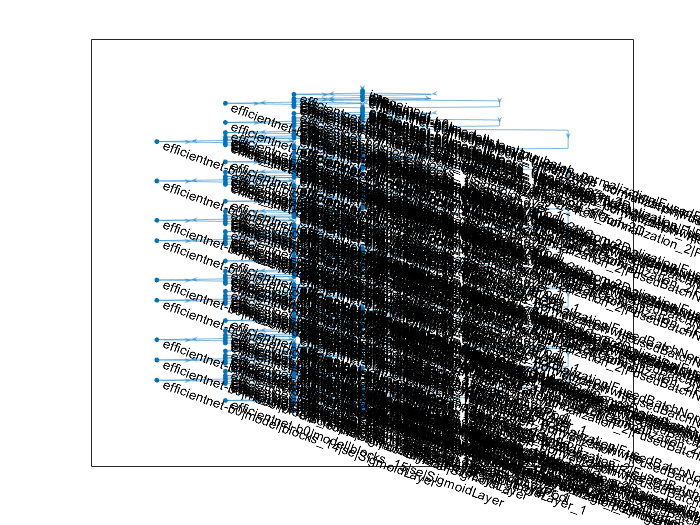

plot(lgraph);

## **Prediction Data**

% Read the image and the corresponding Value(V) component from the csv file.
trainingData = readtable("Train_Aug.csv");
X_Train = trainingData.Name;

testingData = readtable("Test.csv");

Y_Train = trainingData.Value;

Y_Test = testingData.Value;
fn = X_Train{1};
size(imread(fn));
%imshow(imread(fn));

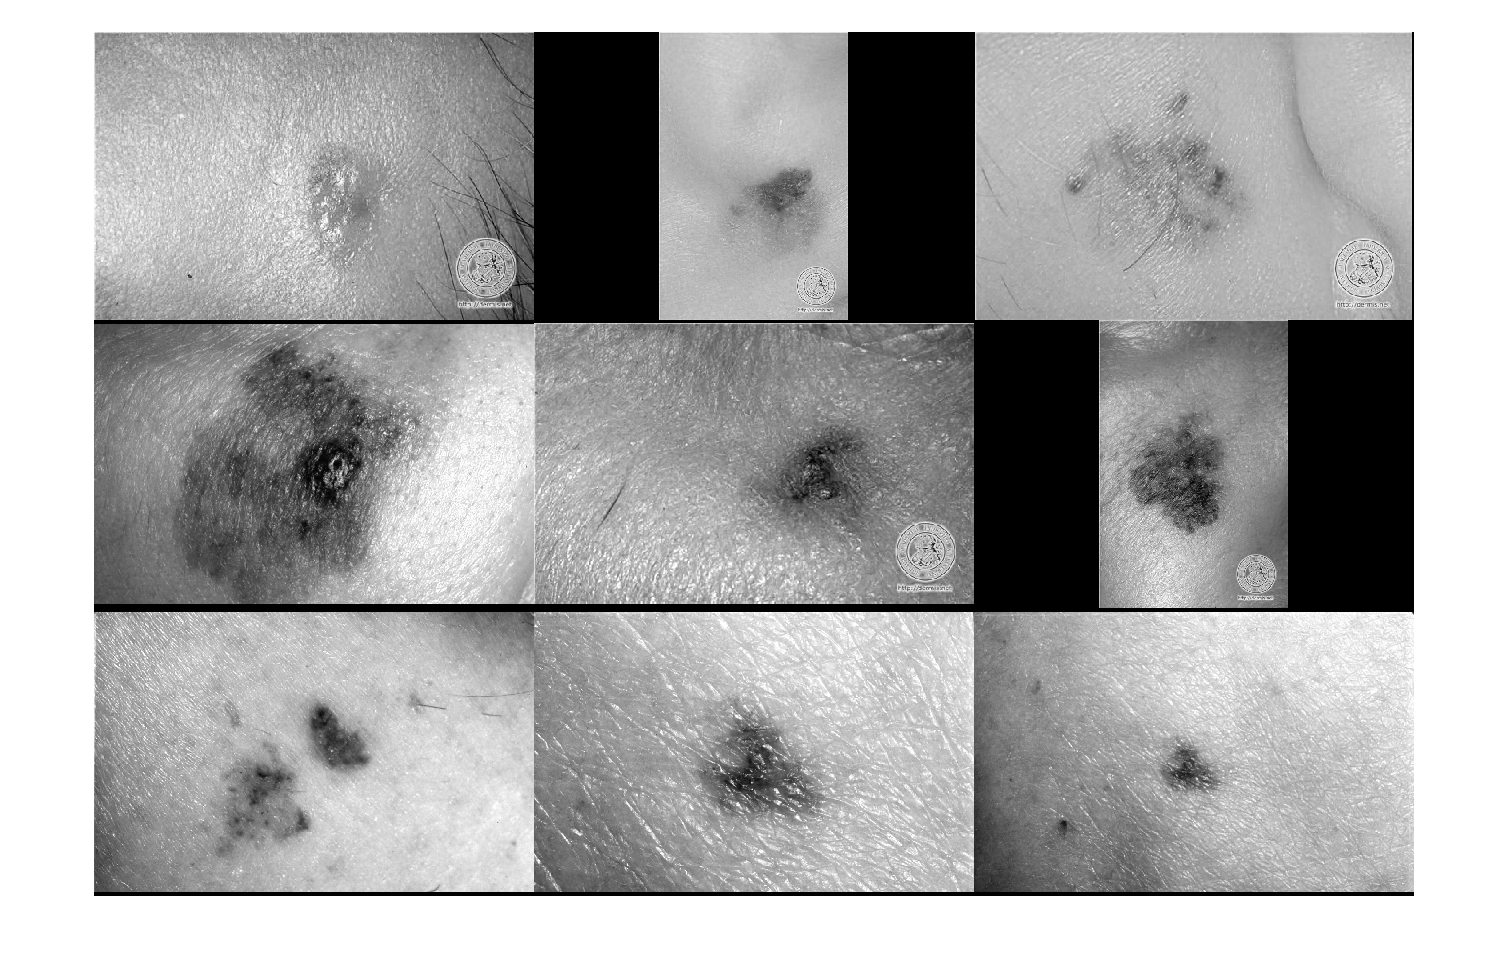

imds = imageDatastore(X_Train(1:9));
montage(imds)

trainds = augmentedImageDatastore([224 224],trainingData)

trainds =   augmentedImageDatastore with properties:

         NumObservations: 2665
           MiniBatchSize: 1
        DataAugmentation: 'none'
      ColorPreprocessing: 'none'
              OutputSize: [224 224]
          OutputSizeMode: 'resize'
    DispatchInBackground: 0


%validds = augmentedImageDatastore([224 224],validData);
testds = augmentedImageDatastore([224 224],testingData)

testds =   augmentedImageDatastore with properties:

         NumObservations: 48
           MiniBatchSize: 1
        DataAugmentation: 'none'
      ColorPreprocessing: 'none'
              OutputSize: [224 224]
          OutputSizeMode: 'resize'
    DispatchInBackground: 0


%Training options
options = trainingOptions("sgdm","MaxEpochs",15,"InitialLearnRate",0.001,'Shuffle','every-epoch', ...
    'MiniBatchSize',16)

options =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9000
                InitialLearnRate: 1.0000e-03
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 15
                   MiniBatchSize: 16
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: []
             ValidationFrequency: 50
              ValidationPatience: Inf
                         Shuffle: 'every-epoch'
                  CheckpointPath: ''
            ExecutionEnvironment: 'auto'
                      WorkerLoad: []
                       OutputFcn: []
                           Plots: 'none'
                  SequenceLength: 


effnet = trainNetwork(trainds,lgraph,options)

Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:10 |         0.69 |          0.2 |          0.0010 |
|       1 |          50 |       00:01:29 |         0.37 |      7.0e-02 |          0.0010 |
|       1 |         100 |       00:02:46 |         0.28 |      3.8e-02 |          0.0010 |
|       1 |         150 |       00:04:04 |         0.25 |      3.2e-02 |          0.0010 |
|       2 |         200 |       00:05:37 |         0.28 |      3.9e-02 |          0.0010 |
|       2 |         250 |       00:06:54 |         0.22 |      2.4e-02 |          0.0010 |
|       2 |         300 |  

effnet =   DAGNetwork with properties:

         Layers: [289×1 nnet.cnn.layer.Layer]
    Connections: [362×2 table]
     InputNames: {'imageinput'}
    OutputNames: {'regressionoutput'}


% Evaluation of the performance matrices for the trained model
Train_Predicted = abs(predict(effnet,trainds))

Train_Predicted = 2665×1 single column vector
    0.0061
    0.6812
    0.6902
    0.3719
    0.3904
    0.2431
    0.2778
    0.4624
    0.4446
    0.1907


Test_Predicted = abs(predict(effnet,testds));

Train_predictionError = Y_Train - Train_Predicted;
Test_predictionError = Y_Test - Test_Predicted;

Train_Pred_mae = errperf(Y_Train,Train_Predicted,'mae')

Train_Pred_mae = single
0.0651

Train_Pred_mse = errperf(Y_Train,Train_Predicted,'mse')

Train_Pred_mse = single
0.0068

Train_Pred_rmse = errperf(Y_Train,Train_Predicted,'rmse')

Train_Pred_rmse = single
0.0826


Test_Pred_mae = errperf(Y_Test,Test_Predicted,'mae')

Test_Pred_mae = single
0.0609

Test_Pred_mse = errperf(Y_Test,Test_Predicted,'mse')

Test_Pred_mse = single
0.0061

Test_Pred_rmse = errperf(Y_Test,Test_Predicted,'rmse')

Test_Pred_rmse = single
0.0781

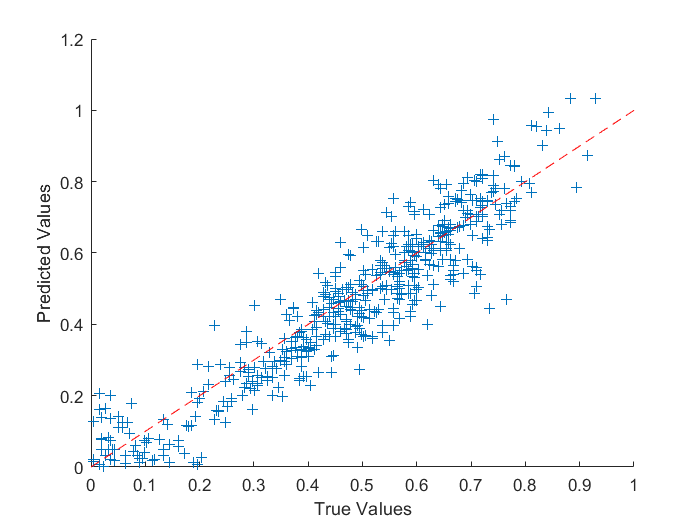

figure
scatter(Y_Train,Train_Predicted,'+')
xlabel("True Values")
ylabel("Predicted Values")

hold on
plot([0 1], [0 1],'r--')

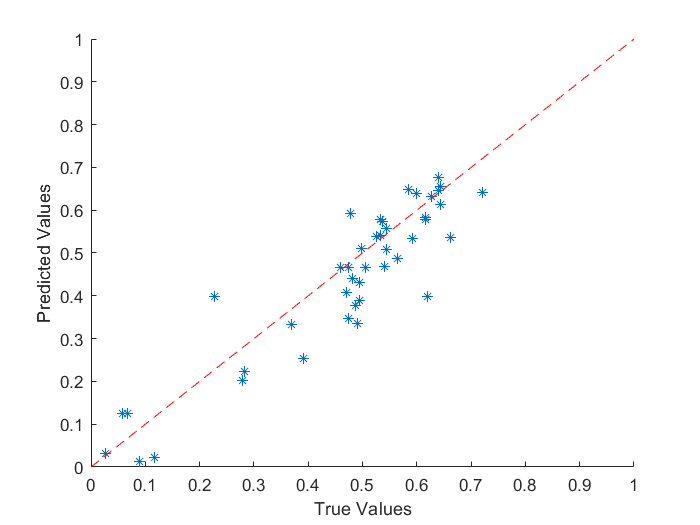

figure
scatter(Y_Test,Test_Predicted,'*')
xlabel("True Values")
ylabel("Predicted Values")

hold on
plot([0 1], [0 1],'r--')

save('Int_effnet_sgdm_224X224_Repeatdata_12_11_21.mat')